clear
% Información del archivo .h5
path = "..\hdf5\A_RS_140819\LFP.h5";
filename = strrep(path, '\', '\\');
dataset = '/LFP';
info = h5info(filename, dataset);
num_times = info.Dataspace.Size(1);

signal = h5read(filename, dataset);

f=8;
narray=0;
for x=0:4
    for y=0:1
        mask = subsample_mask(f, x, y) & floor((0:1023)/64)==narray;
        m = mean(signal(:, mask), 2);
        mean_path = sprintf("subsamples\\subsample_mean_array_%d_f_%d_x_%d_y_%d", narray, f, x, y);
        save(mean_path, "m");
    end
end

f=8;
narray=0;
box_lengths=floor(logspace(1, 6, 100))';
for x=0:4
    for y=0:1
        mean_path = sprintf("subsamples\\subsample_mean_array_%d_f_%d_x_%d_y_%d", narray, f, x, y);
        load(mean_path, "m");
        [~,F] = DFA_fun(m(~isnan(m)), box_lengths, 1);
        dfa_path = sprintf("subsamples\\subsample_dfa_array_%d_f_%d_x_%d_y_%d", narray, f, x, y);
        save(dfa_path, "box_lengths", "F");
    end
end

clear
clf

f=8;
narray=0

narray = 0

fig = figure('Visible', 'off');
fig.Position = [100, 100, 1200, 900];
t = tiledlayout(1,1);
labels = {};
nexttile;
hold on;
for x=0:4
    for y=0:1
        labels{end+1} = sprintf("x=%d y=%d", x, y);
        dfa_path = sprintf("subsamples\\subsample_dfa_array_%d_f_%d_x_%d_y_%d", narray, f, x, y);
        load(dfa_path, "box_lengths", "F")
        plot(log10(box_lengths(1:4:end)), log10(F(1:4:end)), LineStyle="--", Marker=".", MarkerSize=10);
    end
end

x=0;
y=1;
labels{end+1} = sprintf("all arrays x=%d y=%d", x, y);
dfa_path = sprintf("subsamples\\subsample_dfa_f_%d_x_%d_y_%d", f, x, y);
load(dfa_path, "box_lengths", "F")
plot(log10(box_lengths(3:4:end)), log10(F(3:4:end)), LineStyle="--", Marker="+", MarkerSize=20);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
legend(labels);
exportgraphics(t, 'array1_vs_all_subsamples_f_8.png', 'Resolution', 300);


clear
clf
figure;
hold on;
for i=0:6
    f=2^i;
    i
    dfa_path = sprintf("subsample_dfa_f_%d.mat", f);
    load(dfa_path, "box_lengths", "F");

    % calculo la derivada logaritmica (alfa) usando diferencias finitas
    alpha = diff(log(F))./diff(log(box_lengths));
    plot(log10(box_lengths(2:end)), alpha, LineStyle="--", Marker=".", MarkerSize=10);
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

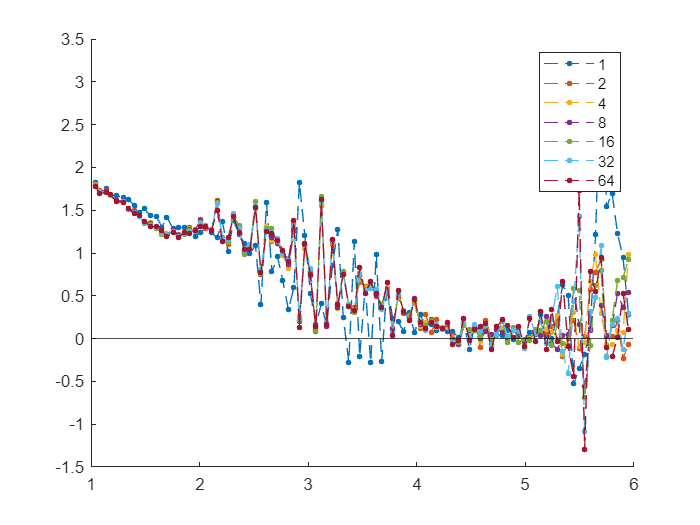

legend(string(2.^(0:6)));
yline(0, 'k', 'HandleVisibility', 'off');
hold off

# POWER SPECTRUM

for i=0:6
    f=2^i;
    i
    mean_path = sprintf("subsample_mean_f_%d", f);
    load(mean_path, "m");
    m=m(~isnan(m));
    ps = pspectrum(m);
    ps_path = sprintf("subsample_powerspectrum_f_%d", f);
    save(ps_path, "ps");
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

clear
clf
figure(1);
for i=0:6
    f=2^i;
    i
    ps_path = sprintf("subsample_powerspectrum_f_%d.mat", f);
    load(ps_path, "ps");
    hold on;
    plot(log10(ps), LineStyle="--", Marker=".", MarkerSize=10);
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

legend(string(2.^(0:6)));
hold off;

clear
clf
fig = figure('Visible','off');

hold on;
for i=0:6
    f=2^i;
    i
    ps_path = sprintf("subsample_powerspectrum_f_%d.mat", f);
    load(ps_path, "ps");
    
    beta = -diff(log(ps))./diff(log(1:length(ps)));
    plot(log10(1:1:length(beta)), beta(1:1:length(beta)), LineStyle="--", Marker=".", MarkerSize=10);
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6


legend(string(2.^(0:6)));
hold off

saveas(fig, 'plot.png');
close(fig)

# AVALANCHAS

threshold = 50;

for i=0:6
    i
    f=2^i;
    mean_path = sprintf("subsample_mean_f_%d", f);
    load(mean_path, "m");
    m=m(~isnan(m));
    %% compute activity
    activity=(m>threshold).*(m-threshold);
    [durations, sizes] = avalanche_hunter(activity);

    ava_path = sprintf("subsample_mean_avalanches_f_%d", f);
    save(ava_path, "durations", "sizes");
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

f=2;
threshold=50;
mean_path = sprintf("subsample_mean_f_%d", f);
load(mean_path, "m");
m=m(~isnan(m));
%% compute activity
activity=(m>threshold).*(m-threshold);

fig = figure('Visible', 'off');
fig.Position = [100, 100, 1200, 900];
t = tiledlayout(4, 2);
nexttile;
plot(activity);
exportgraphics(t, 'ejemplo_actividad.png', 'Resolution', 300);


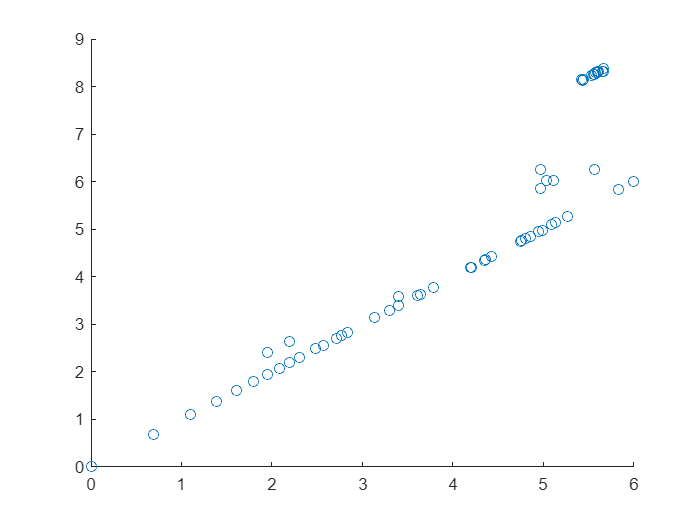

ava_path = sprintf("subsample_avalanches_f_%d", 8);
load(ava_path, "durations", "sizes");
scatter(log(durations), log(sizes));

clear gamma
clf

fig = figure('Visible', 'off');
fig.Position = [100, 100, 1200, 900];

gamma = [];

t = tiledlayout(4, 2);
for i=0:6
    i
    f=2^i;
    ava_path = sprintf("subsample_mean_avalanches_f_%d", f);
    load(ava_path, "durations", "sizes");
    [D, S] = mean_by_group(durations, sizes);

    P = polyfit(log(D),log(S),1);
    fit = polyval(P,log(D));

    ax = nexttile;
    hold on
    plot(log(D), log(S), '--.')
    plot(log(D), fit)
    
    xlabel(ax, "log(T)");
    ylabel(ax, "log(<S>(T))")

    gamma(i+1) = P(1);
    eqn = sprintf("f=%d, gamma=%3f", f, P(1));
    text(min(log(D)),max(log(S)),eqn,"HorizontalAlignment","left","VerticalAlignment","top")
    hold off
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

exportgraphics(t, 'subsample_mean_avalanches.png', 'Resolution', 300);
save("gamma.mat", "gamma");

clear tau_t tau_s
clf

fig = figure('Visible', 'off');
fig.Position = [100, 100, 1200, 900];
t1 = tiledlayout(4, 2);

tau_t = [];
for i=0:6
    i
    f=2^i;
    ava_path = sprintf("subsample_mean_avalanches_f_%d", f);
    load(ava_path, "durations");

    %%%%%%%%%% Distribucion duraciones %%%%%%%%%%%%%
    [counts, centers] = hist(durations);
    P = polyfit(log(centers(counts~=0)),log(counts(counts~=0)),1);
    fit = polyval(P,log(centers(counts~=0)));

    ax = nexttile;
    hold on
    plot(log(centers(counts~=0)), log(counts(counts~=0)), '--.')
    plot(log(centers(counts~=0)), fit)
    
    xlabel(ax, "log(T)");
    ylabel(ax, "log(counts)")

    tau_t(i+1) = -P(1);
    eqn = sprintf("f=%d, tau_T=%3f", f, -P(1));
    text(max(log(centers)),max(log(counts)),eqn,"HorizontalAlignment","left","VerticalAlignment","top")
    hold off
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

exportgraphics(t1, 'subsample_durations_distributions.png', 'Resolution', 300);
save("tau_t.mat", "tau_t");

fig = figure('Visible', 'off');
fig.Position = [100, 100, 1200, 900];
t2 = tiledlayout(4, 2);

tau_s = [];
for i=0:6
    i
    f=2^i;
    ava_path = sprintf("subsample_mean_avalanches_f_%d", f);
    load(ava_path, "sizes");

    %%%%%%%%%%% Distribucion tamaños %%%%%%%%%%%%%%%
    [counts, centers] = hist(sizes);
    P = polyfit(log(centers(counts~=0)),log(counts(counts~=0)),1);
    fit = polyval(P,log(centers(counts~=0)));

    ax = nexttile;
    hold on
    plot(log(centers(counts~=0)), log(counts(counts~=0)), '--.');
    plot(log(centers(counts~=0)), fit);
    
    xlabel(ax, "log(S)");
    ylabel(ax, "log(counts)")

    tau_s(i+1) = -P(1);
    eqn = sprintf("f=%d, tau_S=%3f", f, -P(1));
    text(max(log(centers)),max(log(counts)),eqn,"HorizontalAlignment","left","VerticalAlignment","top")
    hold off
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

exportgraphics(t2, 'subsample_sizes_distributions.png', 'Resolution', 300);
save("tau_s.mat", "tau_s");

fig = figure('Visible', 'off');
t = tiledlayout(1, 1);
nexttile;
scatter((tau_t-1)./(tau_s-1), gamma);
exportgraphics(t, 'exponents_relation.png', 'Resolution', 300);